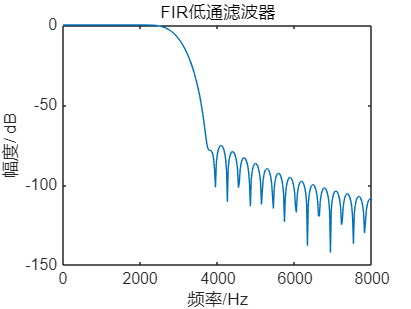

clc;clear;
[y0,Fs]=audioread('dspx1.wav');
t = (0:length(y0)-1) / Fs;
n = length(y0); 
f=4000;
A=0.02;
Nt=(A*cos(2*pi*f*t))';
y=y0+Nt;
%利用布莱克曼窗，通带截至频率2000Hz，阻带截至频率3800Hz
wp=2000*2*pi/Fs;
ws=3800/Fs*2*pi;
wide=ws-wp;
N=ceil(12*pi/wide)+1;
wc=(wp+ws)/2;
h=fir1 (N, wc/pi, blackman(N+1)) ;
[H, w]=freqz(h,1,1000) ;
w=w/2/pi*Fs;
plot(w,20*log10(abs(H)));
xlim([0,8000]);
xlabel('频率/Hz') ; 
ylabel('幅度/ dB') ;
title('FIR低通滤波器');

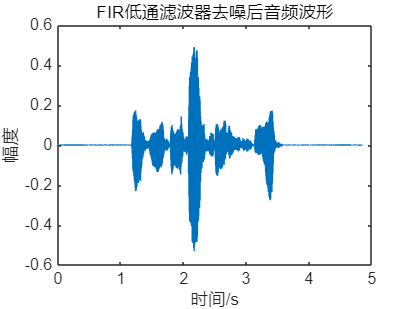

%利用布莱克曼窗去噪
y3=filter(h,1,y);
figure;
plot(t,y3);
title('FIR低通滤波器去噪后音频波形');
xlabel('时间/s');
ylabel('幅度');

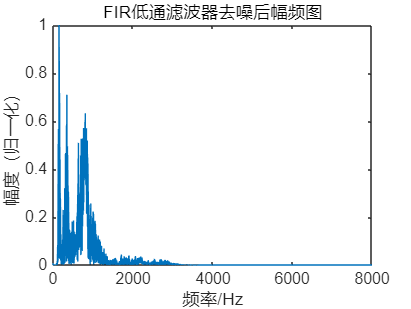

figure;
Y3 = fft(y3); 
M1=max(Y3);
f = (0:n-1)*Fs/n;
Y3 = abs(Y3)/abs(M1); 
plot(f, Y3);
title('FIR低通滤波器去噪后幅频图');
xlabel('频率/Hz');
ylabel('幅度（归一化）');
xlim([0,8000]);